n = 100;


ers_t = randi([-4,4],n,1)

ers_t =     -4
    -2
    -4
    -1
    -1
     0
     4
    -2
    -1
     3


ers_a = (2 * rand(n,1) - 1)

ers_a =     0.1357
   -0.4021
   -0.4878
    0.7731
   -0.1064
    0.6320
   -0.8033
    0.7192
   -0.9447
    0.7983


ttx = tt_tgt(2000:2500,:);
global ttx
global er_a
global er_t


% evaluate on each of the 100 random transformations
b_init = 0.1;
b_opt = [];
cost = [];
for i2 = 1:n
    % apply transofmration
    er_t = ers_t(i2);
    er_a = ers_a(i2);
    
    
%     bs = 0.000001:0.000001:0.005;
%     costi = [];
    
%     for i3 = 1:numel(bs)

b = b_init;


[b_opt(i2),cost(i2)] = fmincon(@optfun,b,[],[],[],[],0,1)
%     optfun(b)
%     b = 0.001;
%         b = bs(i3);
        
%         [~,max_ind] = max(costi);
%         b_opt(i2) = bs(max_ind);
%     end
end

nan_seg_starts =      1   502


kill
plot3(ers_a,ers_t,-cost,'o')



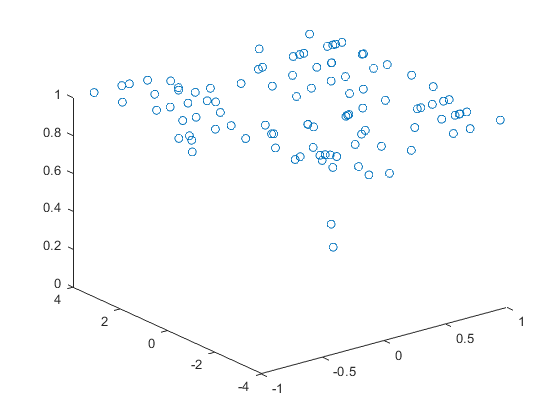


cost = [];
for i2 = 1:n
    er_t = ers_t(i2);
    er_a = ers_a(i2);
    cost(i2) = optfun(median(b_opt));
end
plot3(ers_a,ers_t,-cost,'o')
zlim([0,1])

bs = [0,0.1,1]

bs =          0    0.1000    1.0000


cost = [];
i3 = 5;
for i2 = 1:numel(bs)
    er_t = ers_t(i3);
    er_a = ers_a(i3);
    b = bs(i2);
    cost(i2) = optfun(b);
end
plot(bs,cost,'o')

function cost = optfun(b)
global ttx
global er_a
global er_t
ttx0 = ttx;
ttx0 = lag(ttx,-er_t);
ttx0.Variables = ttx0.Variables - er_a;
        [hmt, hma] = perf_hm(ttx.Variables,ttx0.Variables,[4,4],b);
        cost = sum((((hma-er_a).^2) + (b.^2 * (hmt-er_t).^2)));
end